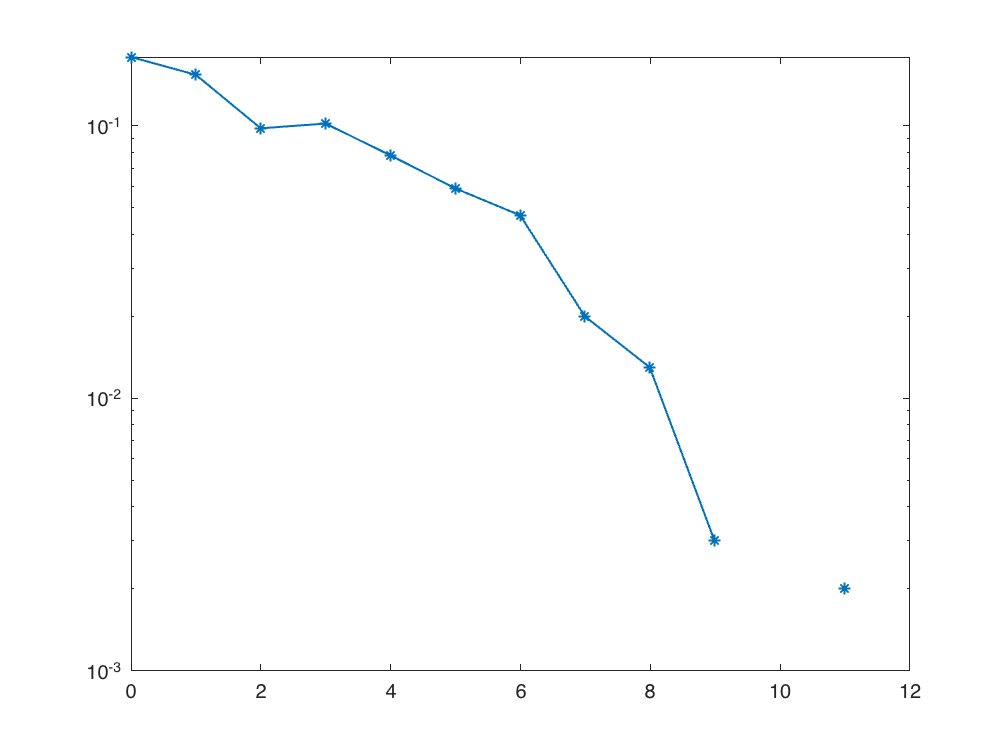

% unipolar
global Tsampling t
Tsampling = 1e-7 ; 
fsampling = 1/Tsampling ; 
alphabet = [-3,-1,1,3] ; 
Tb = 1e-6 ; 
Ts = Tb * log2(length(alphabet)) ; 
nbits = 1000 ; nsymbols = nbits / log2(length(alphabet)) ;
N0 = logspace(log10(2.5),-1.5,20);

Eb=2.5;
Eb_ratio=zeros(1,length(N0));
BER=zeros(1,length(N0));
t = (0:Tsampling:(nsymbols*Ts-Tsampling)) ; 
% Transmitted bits
tx_bits = round(rand(1,nbits)) ; 
% Transmitted symbols
tx_symbols = map(tx_bits,alphabet) ;
% Transmitted signal (channel input)
tx_signal = modulate(tx_symbols,Ts,nsymbols) ; 
for j=1:length(N0)
    % Received signal (channel output)
    rx_signal = tx_signal + sqrt(fsampling * N0(j)/2) * randn(1,length(t)) ; 
    % Received symbols
    rx_symbols = demodulate(rx_signal,Ts,nsymbols) ; 
    % Received bits
    rx_bits = demap(rx_symbols,alphabet) ;
    
    Eb_ratio(j)=10*log10(Eb/N0(j));
    counter=0;
    for i=1:length(rx_bits)
        if(rx_bits(i)~=tx_bits(i))
            counter=counter+1;
        end
    end
    BER(j)=counter/length(rx_bits);
end
semilogy(Eb_ratio,BER,'-*',LineWidth=1)

function tx_symbols = map(tx_bits,alphabet)
    nbits_tx_sy = log2(length(alphabet));
    length_tx_symbols = length(tx_bits)/nbits_tx_sy;
    aux_0 = reshape(tx_bits,[nbits_tx_sy,length_tx_symbols]);
    aux=aux_0';
    for k = 1:length_tx_symbols
        tx_symbols(k) = alphabet(bi2de(aux(k,:))+1);
    end
end 

% Task 1.2 Baseband Modulator
function tx_signal = modulate(tx_symbols,Ts,nsymbols) 
    global t
    tx_signal = zeros(1,length(t)) ;
    for k = 1:nsymbols
        tx_signal = tx_signal + tx_symbols(k) * (1/sqrt(Ts) * rectpuls(t-Ts/2-(k-1)*Ts,Ts)) ;
    end
end

% Task 2.1 Demodulator
function rx_symbols = demodulate(rx_signal,Ts,nsymbols)
    global t
    global Tsampling
    rx_symbols = zeros(1, length(nsymbols));
    for k = 1:nsymbols
        rx_symbols(k) = Tsampling * sum(rx_signal .* (1/sqrt(Ts) * rectpuls(t- Ts/2-(k-1)*Ts,Ts))) ;
    end
end

% Task 2.2 Demapper
function rx_bits = demap(rx_symbols,alphabet)
    rx_bits = zeros(log2(length(alphabet)),length(rx_symbols)) ; 
    for k1 = 1:length(rx_symbols)
        aux = Inf ;
        for k2 = 1:length(alphabet)
            if (rx_symbols(k1) - alphabet(k2))^2 < aux
                aux = (rx_symbols(k1) - alphabet(k2))^2 ;
                rx_bits(:,k1) = de2bi(k2-1,log2(length(alphabet)))' ;
            end 
        end
    end 
    rx_bits = reshape(rx_bits,length(rx_bits)*log2(length(alphabet)),1)';
end

